# PATIPPET simulations for manuscript

## Tempo estimation

PATIPPET initially expects a range of tempi centered on 1. But in a few clicks, it recognizes the real tempo and develops a high degree of confidence in its estimate.

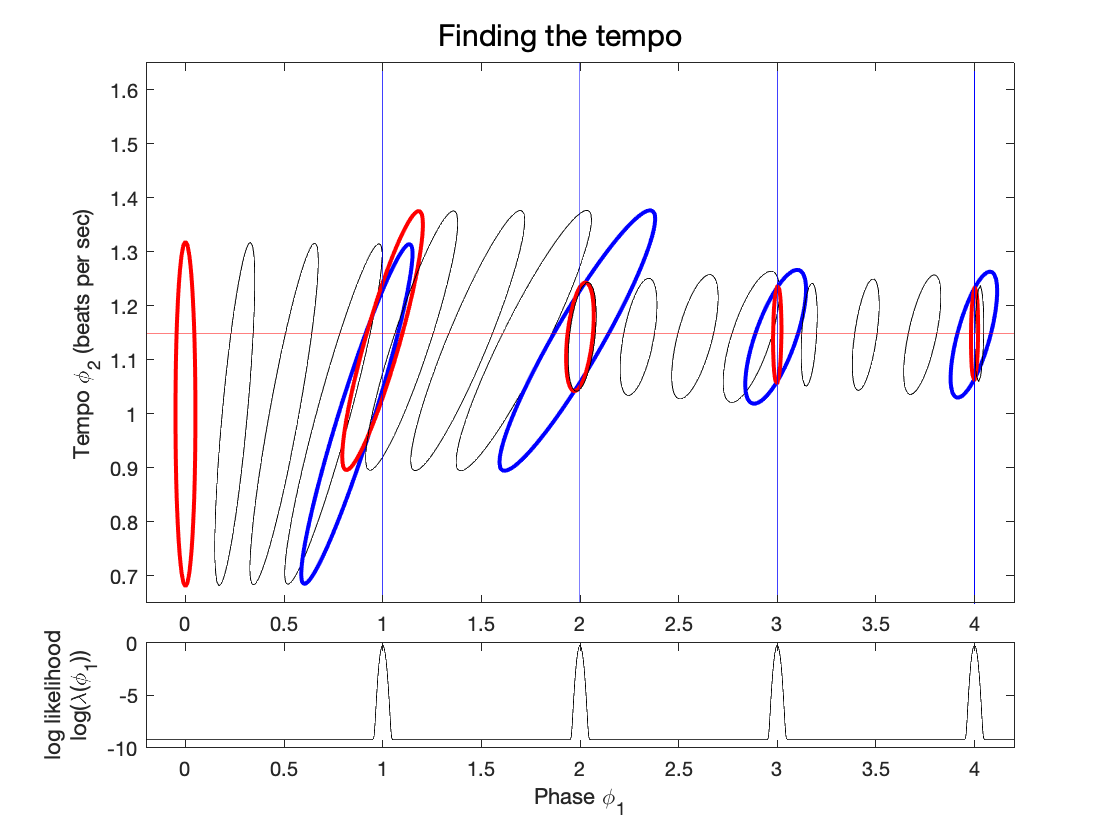


true_tempo = 1.15;
period = 1/true_tempo;

params = PATIPPET_params(...
    'events_unit', [1],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'true_speed', true_tempo,...
    'event_times', period:period:4*period,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'mu_0', [0, 1],...
    'C_0', [.001,0; 0,.04],...
    'lambda_0', .0001,...
    'dt_ellipse',.25,...
    'title', 'Finding the tempo');
[mu_list, C_list] = run_PATIPPET(params);

## Phase shift as a function of tempo

PATIPPET is given time to entrain to four different tempi, and then given a phase shifted click. Taps are assumed to happen each time the mean estimated phase reaches an integer, except at the phase shift, which is assumed to take place too close to a tap for that tap to adjust. Tap times are used to 

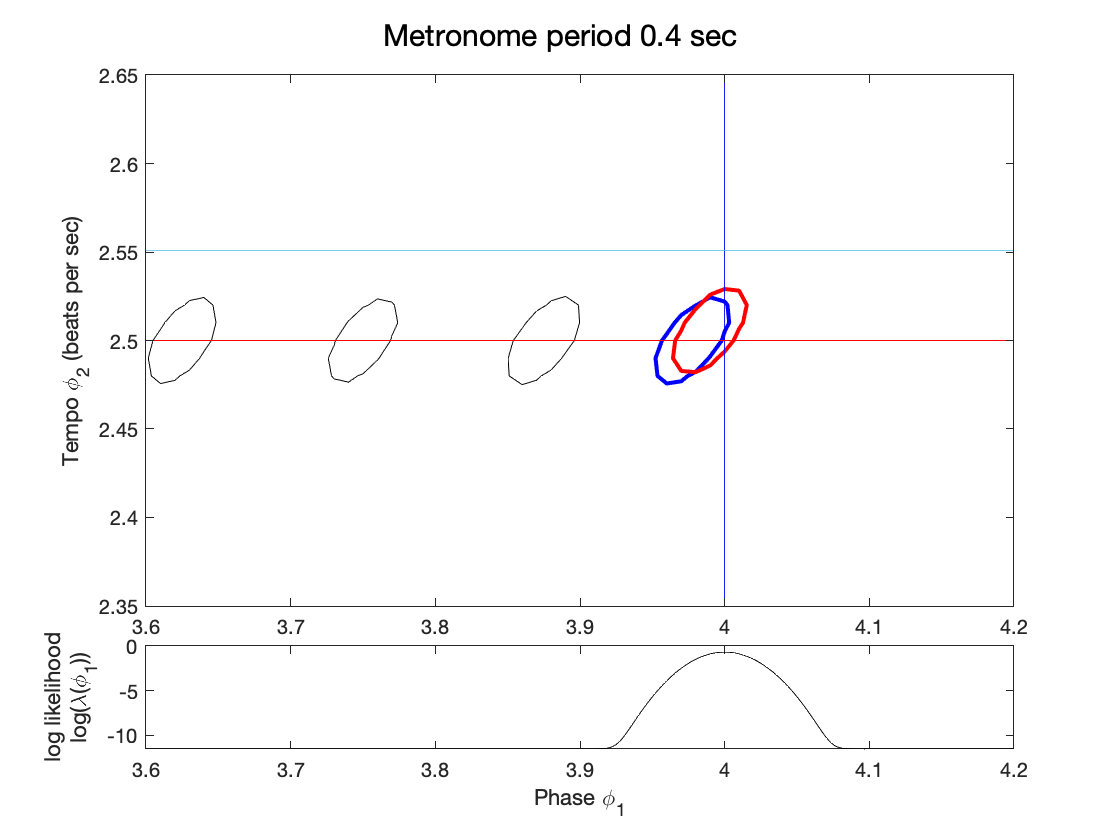

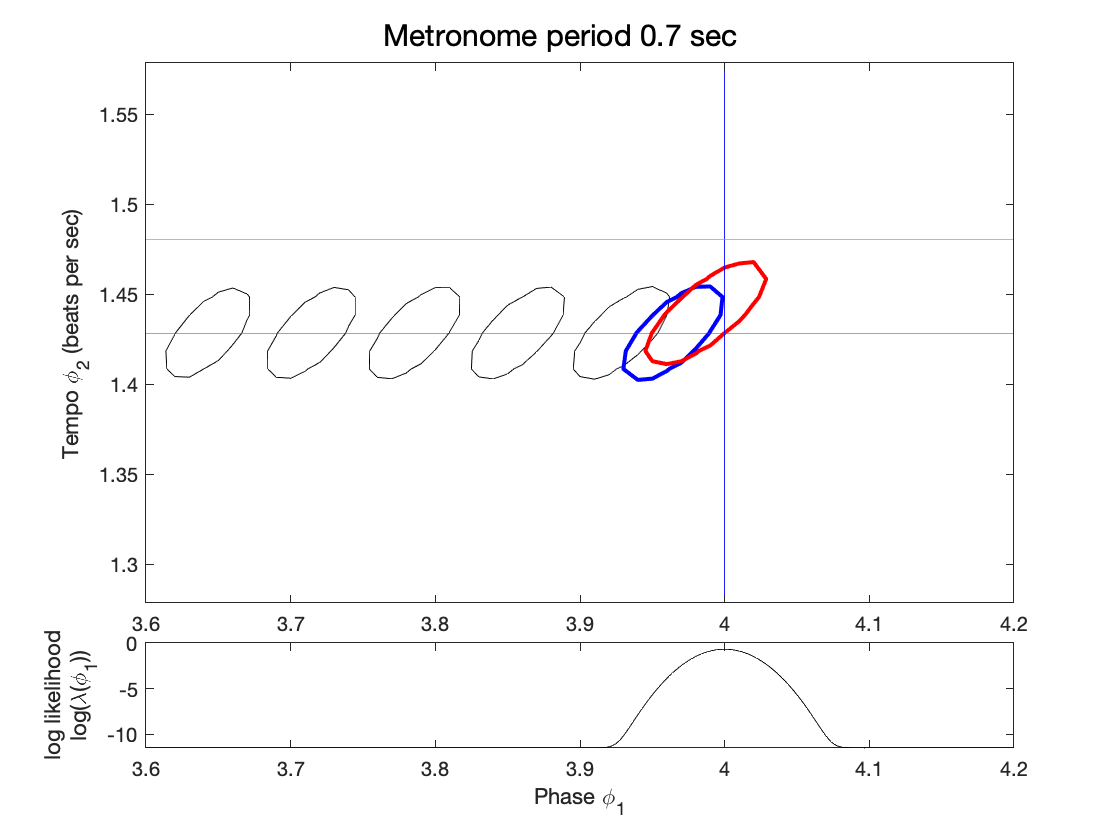

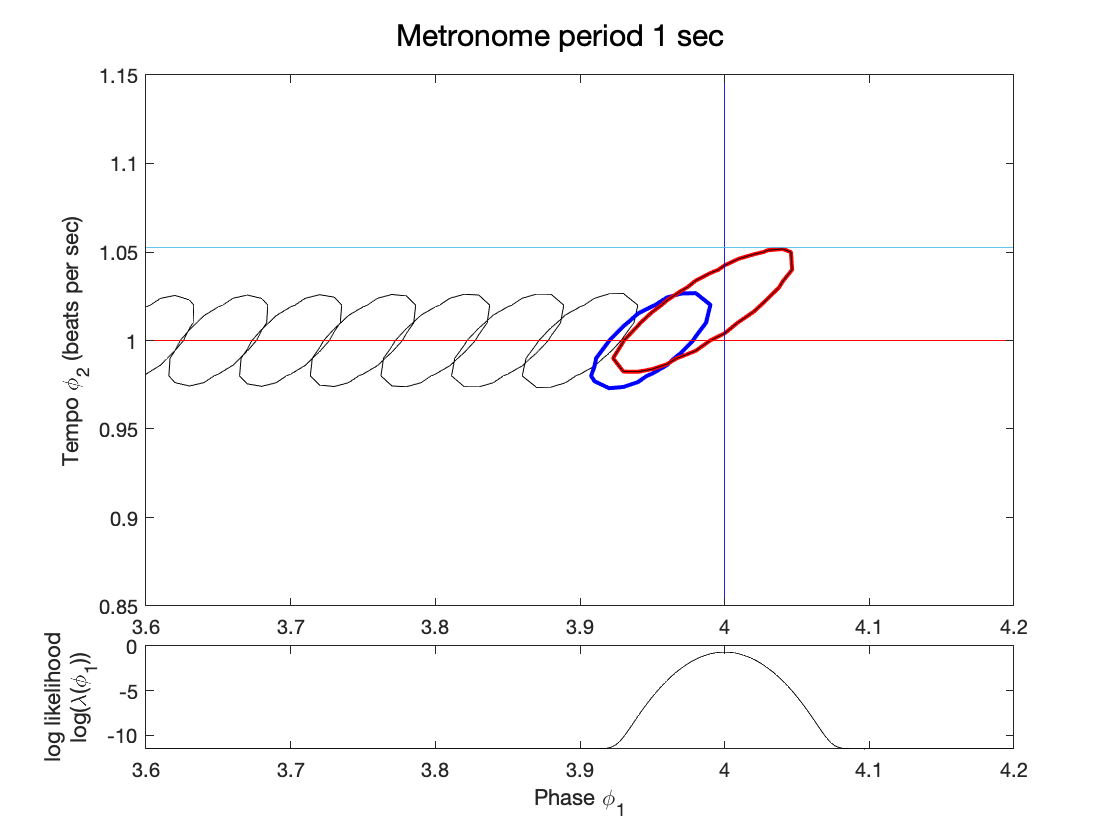

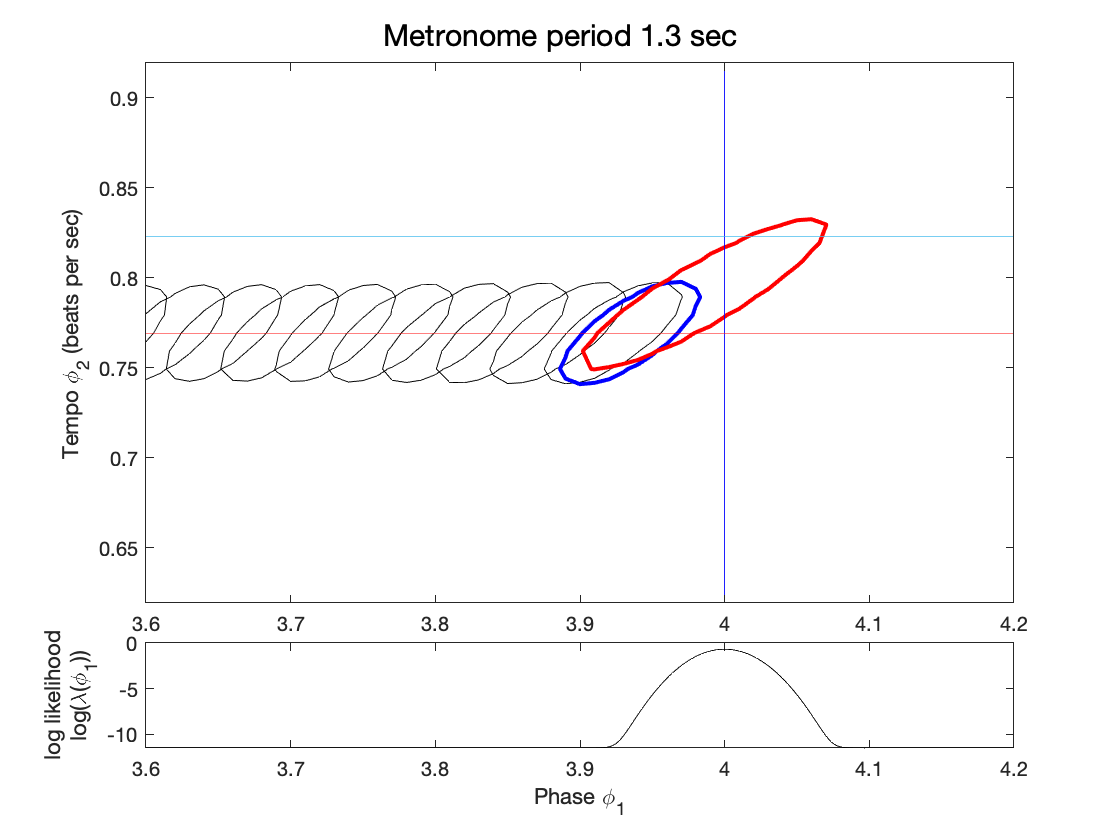


dt = .001;

params = PATIPPET_params(...
    'events_unit', [1],...
    'variance_unit', [.00025],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'sigma', 0.01,...
    'sigma_2', 0.01,...
    'lambda_0', .00001,...
    'C_0', [.0001, 0; 0, .0001],...
    'dt_ellipse', .05,...
    'display', true);

period_list = [.4, .7, 1, 1.3];

%%% Any of the following phase shift schemes give similar results, but the
%%% first makes prettier pictures.

delta_list = -period_list.^2 / 20; % phase shifts corresponding to equal tempo changes
%delta_list = -period_list / 25; % phase shifts proportional to period
%delta_list = -.01*ones(size(period_list)); % identical phase shifts

mu_final_list = zeros(2, length(period_list));
mu_initial_list = zeros(2, length(period_list));
C_final_list = zeros(2,2, length(period_list));
C_initial_list = zeros(2,2, length(period_list));

for i = 1:length(period_list)
    params.streams{1}.event_times = [period_list(i), 2*period_list(i), 3*period_list(i), 4*period_list(i)+delta_list(i)];
    params.tmax = 4*period_list(i)+delta_list(i);
    params.true_speed = 1/period_list(i);
    params.mu_0 = [0, 1/period_list(i)];
    params.title = "Metronome period " + num2str(period_list(i))+ " sec";
    
    [mu_list, C_list] = run_PATIPPET(params);
    ylim([1/period_list(i) - .15, 1/period_list(i)+.15])
    xlim([3.6, 4.2])
    plot([3.6, 4.2], [1,1]*(1./(period_list(i)+delta_list(i))));
    subplot(5,1,5)
    xlim([3.6, 4.2])
    mu_final_list(:, i) = mu_list(:, end);
    mu_initial_list(:, i) = mu_list(:, end-1);
    C_final_list(:,:, i) = C_list(:, :,end);
    C_initial_list(:,:, i) = C_list(:, :,end-1);
    
    
end


fourth_tap_times = 4*period_list;

phase_until_next_tap = 5 - mu_final_list(1,:);

time_until_next_tap = phase_until_next_tap./mu_final_list(2,:);

fifth_tap_times = fourth_tap_times + delta_list + time_until_next_tap;

next_asynchrony = (5*period_list + delta_list) - fifth_tap_times;

alpha_list = (delta_list-next_asynchrony)./delta_list;

figure()
hold on
plot(period_list, -(mu_final_list(1,:)-mu_initial_list(1,:))./(delta_list/period_list), 'o-')
plot(period_list, (mu_final_list(2,:) - mu_initial_list(2,:))./(1./(period_list + delta_list) - 1./period_list), 'o-')
%plot(period_list, mu_initial_list(1,:), 'o-')
ylabel('Fraction corrected')
xlabel('Metronome period (sec)')
lgd = legend('Phase (\mu_1)', 'Tempo (\mu_2)');

lgd =   Legend (Phase (\mu_1), Tempo (\mu_2)) with properties:

         String: {'Phase (\mu_1)'  'Tempo (\mu_2)'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7357 0.8214 0.1554 0.0845]
          Units: 'normalized'

  Show all properties


lgd.Location = 'northwest'

lgd =   Legend (Phase (\mu_1), Tempo (\mu_2)) with properties:

         String: {'Phase (\mu_1)'  'Tempo (\mu_2)'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1446 0.8214 0.1554 0.0845]
          Units: 'normalized'

  Show all properties


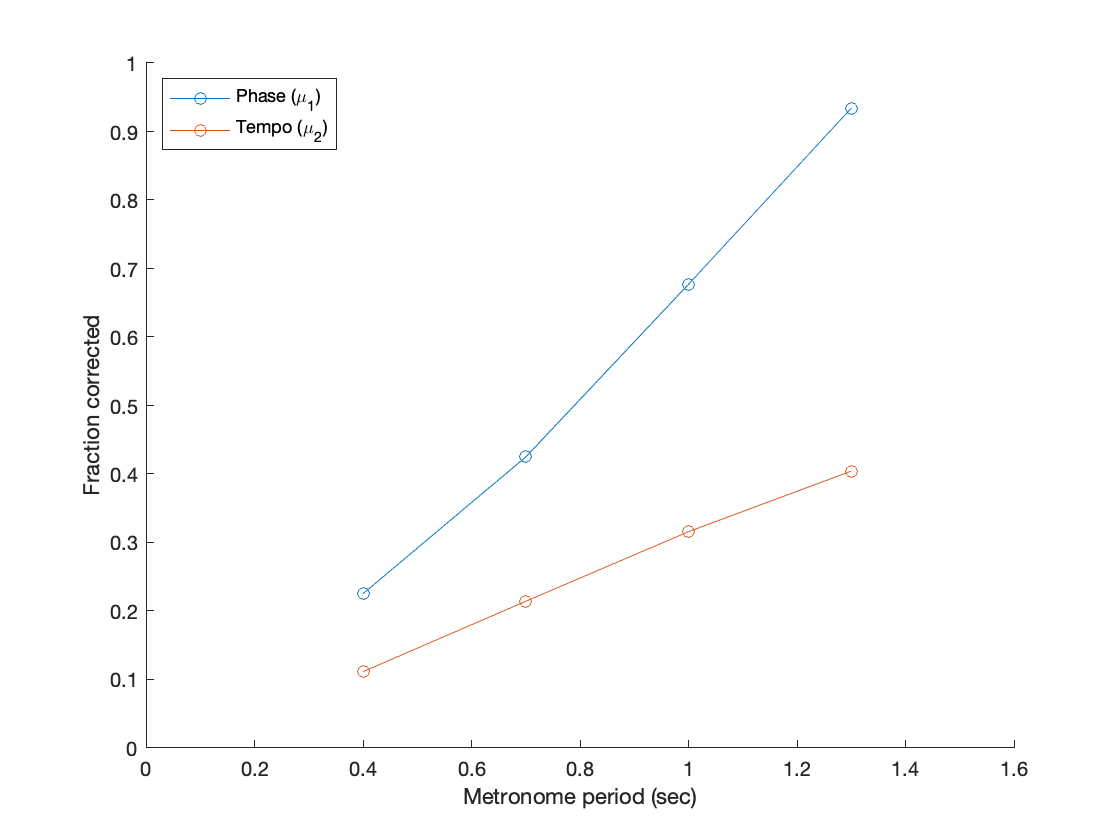

xlim([0, 1.6])
ylim([0, 1])

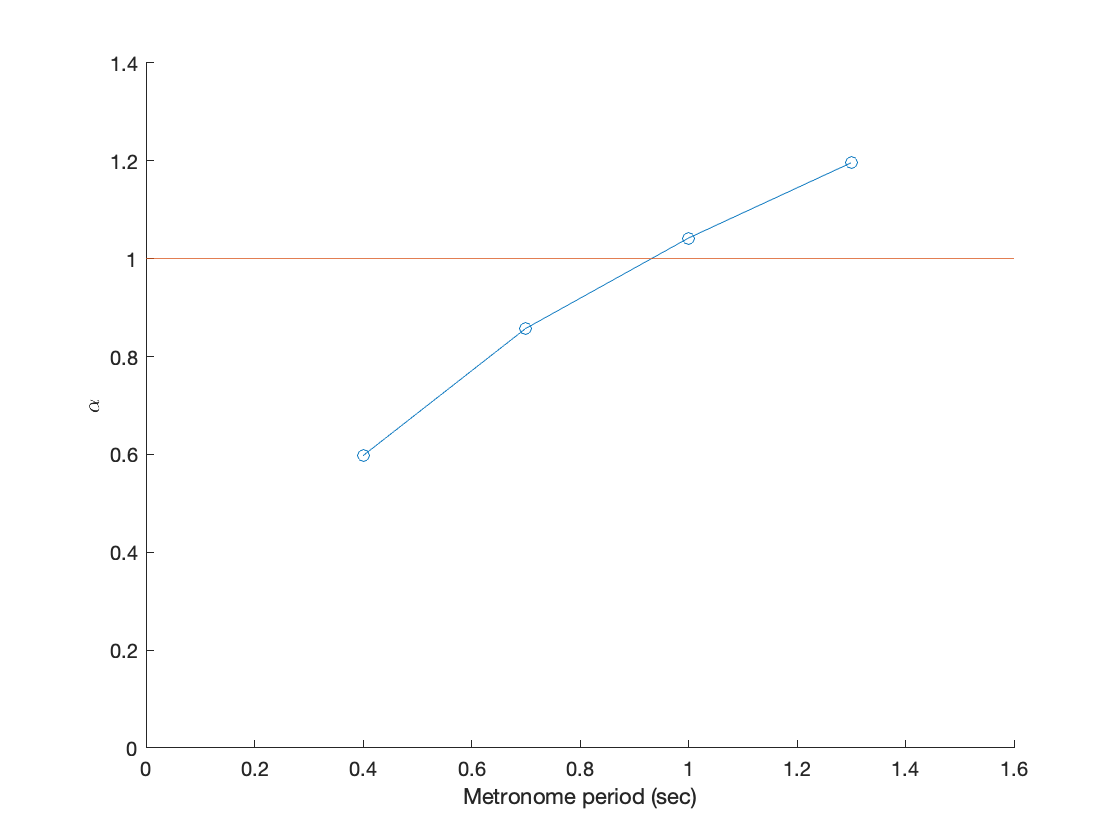

%ylim([3.9, 4])


figure()
hold on
plot(period_list, alpha_list, 'o-')
plot([0,1.6], [1,1], '-')
ylabel('\alpha')
xlabel('Metronome period (sec)')
xlim([0, 1.6])
ylim([0, 1.4])